Lab4 第一題

x = [2 2 2]; h = [2 2 2]; y = conv(x, h)

y =      4     8    12     8     4


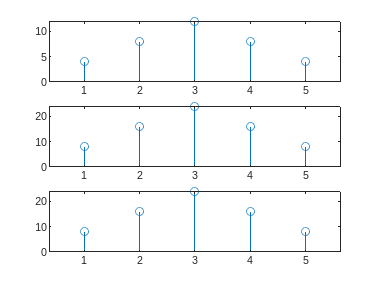

subplot(311);   stem(y);
x = [4 4 4]; y = conv(x, h);
subplot(312);   stem(y);
x = [2 2 2]; h = [4 4 4]; y = conv(x, h);
subplot(313);   stem(y);

%The relationship between the lengths of x, h, and the output y is:
%"length of y" = "length of x" + "length of h" - 1

Lab4 第二題

figure;
N = 256; fs = 8000; freqStep = fs/N; time = (0:N-1)/fs; f = 10*freqStep;
x = cos(2*pi*f*time); h = [1 1 1]; y = conv(x, h)

y =     1.0000    1.9700    2.8520    2.5929    2.1784    1.6334    0.9905    0.2882   -0.4314   -1.1251   -1.7514   -2.2727   -2.6578   -2.8836   -2.9365   -2.8135   -2.5218   -2.0789   -1.5115   -0.8535   -0.1443    0.5736    1.2570    1.8652    2.3615    2.7163    2.9082    2.9259    2.7682    2.4446    1.9744    1.3859    0.7144    0.0000   -0.7144   -1.3859   -1.9744   -2.4446   -2.7682   -2.9259   -2.9082   -2.7163   -2.3615   -1.8652   -1.2570   -0.5736    0.1443    0.8535    1.5115    2.0789


subplot(211);   stem(y);
x = [2 1; 3 2]; h = [-1 1; 2 1]; y = convn(x, h)

y =     -2     1     1
     1     5     3
     6     7     2


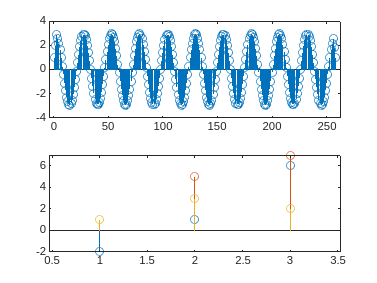

subplot(212);   stem(y);

Lab4 第三題

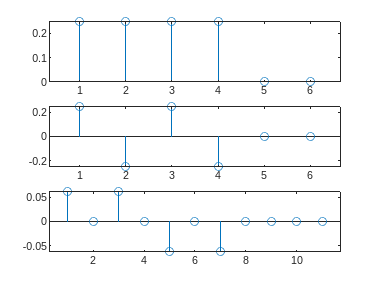

figure;
n = ( 0 : 5 );
h1 = [1/4 1/4 1/4 1/4 0 0]; h2 = [1/4 -1/4 1/4 -1/4 0 0];
u = n >= 0;
fig = conv2(h1.*u, h2.*u);
subplot(311);   stem(h1.*u);
subplot(312);   stem(h2.*u);
subplot(313);   stem(fig);

Lab4 第四題

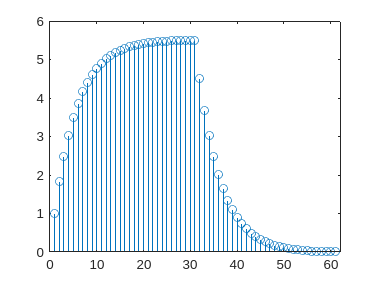

figure;
t = 0 : 0.1 : 3; u = t >= 0;
a = 2; f = 20;
x1 = exp((-a)*t).*u; x2 = cos(2*pi*f*t).*u;
y = conv(x1, x2);
stem(y);

Lab4 第五題

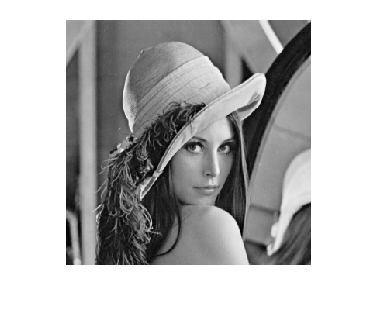

figure;
img = imread('Lenna.jpg'); 
gray_img = rgb2gray(img);
hh = [0.1 -0.1; 0.1 -0.1]; 
hv = [0.1 0.1; -0.1 -0.1];
img_hh = convn(gray_img, hh); 
img_hv = convn(gray_img, hv);
imshow(gray_img, []);

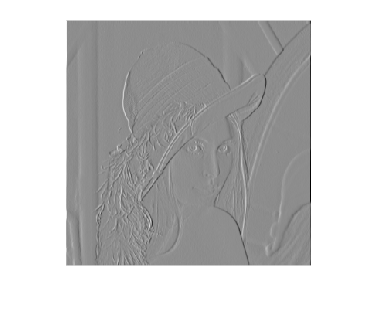

imshow(img_hh, []); 

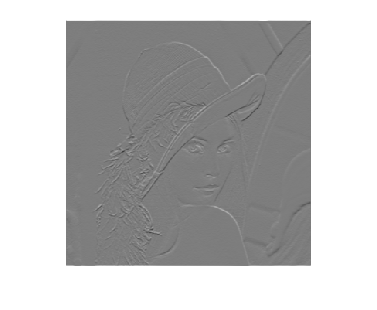

imshow(img_hv, []);

%The figure which convolved with hh is more clear at vertical line.
%The figure which convolved with hv is more clear at horizontal line.